# threshold-duration sensitivity

## load parameters

dur   = [6, 8, 10, 12, 16, 32, 64, 70, 150]; % will pad 4 blank screens to the front and 4 to the end
ndur  = length(dur);

ctr   = [0.005, 0.01, 0.02, 0.05, 0.11, 0.2, 0.4, 0.6, 0.8, 1]; 
nlev  = length(ctr);

% stimulus size in the spatial dimension
sz    = [50, 50];
% blank padding
blank = ones([sz, 4]).*0.5;

% load model parameters
pars  = shPars;

## make contrast and duration stimuli

s_ctr = {};
s_coh = {};

[s_ctr, s_coh] = mkStim(dur, ctr, sz, blank);

## compute v1 and MT response to changing contrast and coherence

rsp_v1ctr = {};
rsp_v1coh = {};

rsp_mtctr = {};
rsp_mtcoh = {};

[cs_v1ctr, cs_v1coh, cs_mtctr, cs_mtcoh] = computeRsp(s_ctr, s_coh, pars, nlev, ndur);

## Visualize  v1 responses

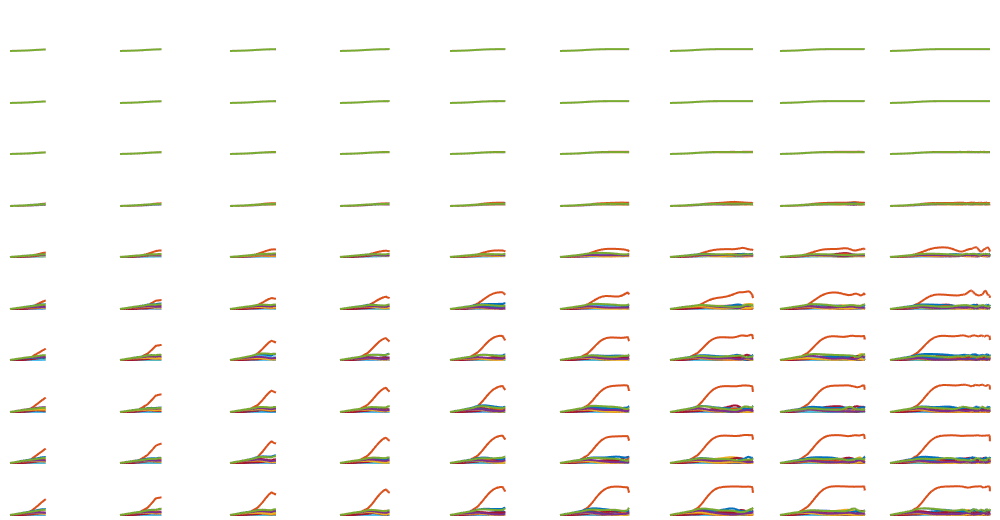

toPlot = cs_mtctr;

fg1 = figure (1); clf, set(fg1, 'Position', [1200, 918, 1000, 520])
for k = 1 : nlev
   for k1 = 1 : ndur
       subplot_tight(nlev, ndur, (k - 1)* ndur + k1, 0.01), 
        semilogx(toPlot{k, k1}), xlim([0, dur(end)]), ylim([0, 0.04]), axis off, 
   end
end

## read-out

% maximum read-out rule
readout_rule = 'max_rsp'; % 'max_rsp', 'pct_rsp'
thresh    = 0.015;
thr_ctr   = zeros(size(cs_mtctr));
thr_coh   = zeros(size(cs_mtctr));
tg_neuron = 2;

for k = 1 : nlev
    for k1 = 1 : ndur
        switch readout_rule
            case 'max_rsp'
                if max(cs_mtctr{k, k1}(:))>=thresh, thr_ctr(k, k1) = 1; end
                if max(cs_mtcoh{k, k1}(:))>=thresh, thr_coh(k, k1) = 1; end
            case 'pct_rsp'
                tgrsp_ctr = cs_mtctr{k, k1}(:, tg_neuron);
                tgrsp_coh = cs_mtcoh{k, k1}(:, tg_neuron);
                tmp1 = cs_mtctr{k, k1}(:, [1 : tg_neuron-1, tg_neuron + 1 : end]);
                tmp2 = cs_mtcoh{k, k1}(:, [1 : tg_neuron-1, tg_neuron + 1 : end]);
                
                if max(tgrsp_ctr)> thresh*mean(tmp1(:)), thr_ctr(k, k1) = 1; end
                if max(tgrsp_coh)> thresh*mean(tmp2(:)), thr_coh(k, k1) = 1; end      
                
            %   max(tgrsp_ctr)
            %    mean(tmp1(:))
    end
end
end

% get threshold
for k = 1 : ndur
    tmp = find(thr_ctr(:, k)==1, 1);
    if isempty(tmp), t_ctr(k) = 1; else,  t_ctr(k) = ctr(tmp); end
    
    tmp1 = find(thr_coh(:, k)==1, 1);
    if isempty(tmp1), t_coh(k) = 1; else, t_coh(k) = ctr(tmp1); end
end

## visualize read-out

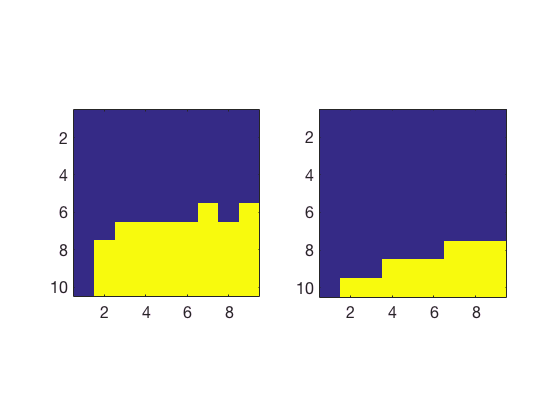

figure (2), clf
subplot(1, 2, 1), imagesc(thr_ctr), axis square
subplot(1, 2, 2), imagesc(thr_coh), axis square

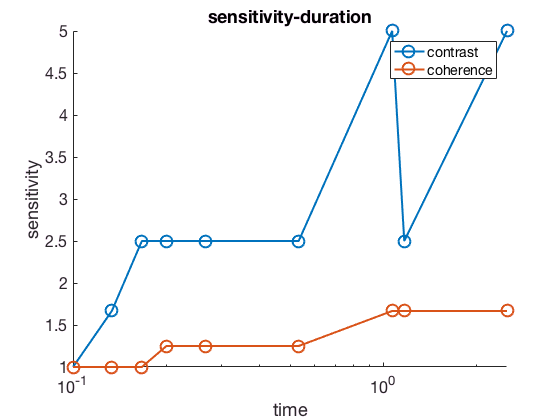

figure (3), clf
semilogx(dur./60, 1./t_ctr, 'o-'), hold on
semilogx(dur./60, 1./t_coh, 'o-'), legend('contrast', 'coher  ence'), axis tight
title('sensitivity-duration'), box off, xlabel('time'), ylabel('sensitivity')

## Sub-functions

function [s_ctr, s_coh] = mkStim(dur, ctr, sz, blank)
s_ctr  = {};
s_coh  = {};
% stimulus inputs:
dotDir = 0;
dotSpd = 1;

ndur   = length(dur);
nlev   = length(ctr);

for k = 1 : ndur
    stimSz = [sz, dur(k)];
    for k1 = 1 : nlev
        tmp = 0.5 + (mkDots(stimSz, dotDir, dotSpd, 0.1, 1) - 0.5).*ctr(k1);
        s_ctr{k1, k} = cat(3, blank, tmp, blank);
        s_coh{k1, k} = cat(3, blank, ...
            mkDots(stimSz, dotDir, dotSpd, 0.1, ctr(k1)), blank);
    end
end
end

% RESHAPE RESPONSE ----------------------------------------------------------------
function rs_rsp = reshapeRsp(rsp, ind)
tmp    = ind(2, :);
nrsp   = reshape(rsp, [tmp(2)*tmp(3), tmp(4), size(rsp, 2)]);
rs_rsp = squeeze(mean(nrsp));
end

% COMPUTE RESPONSE ----------------------------------------------------------------
function [cs_v1ctr, cs_v1coh, cs_mtctr, cs_mtcoh] = computeRsp(s_ctr, s_coh, pars, nlev, ndur)
for k = 1 : nlev
    for k1 = 1 : ndur
        % compute V1 complex cell responses
        [tmp_v1_ctr, ind1] = shModel(s_ctr{k, k1}, pars, 'V1Complex');
        [tmp_v1_coh, ind2] = shModel(s_coh{k, k1}, pars, 'V1Complex');
        
        % reshape the response and take mean across space
        rsp_v1ctr{k, k1} = reshapeRsp(tmp_v1_ctr, ind1);
        rsp_v1coh{k, k1} = reshapeRsp(tmp_v1_coh, ind2);
        % compute cumulative sum
        %cs_v1ctr{k, k1} = cumsum(rsp_v1ctr{k, k1}, 1);
        %cs_v1coh{k, k1} = cumsum(rsp_v1coh{k, k1}, 1);
        
        % compute windowed summation
        cs_v1ctr{k, k1} = win_cumsum(rsp_v1ctr{k, k1}, 60);
        cs_v1coh{k, k1} = win_cumsum(rsp_v1coh{k, k1}, 60);
        
        % compute MT cell responses
        [tmp_mt_ctr, ind1] = shModel(s_ctr{k, k1}, pars, 'mtPattern');
        [tmp_mt_coh, ind2] = shModel(s_coh{k, k1}, pars, 'mtPattern');
        
        % reshape the response and take mean across space
        rsp_mtctr{k, k1} = reshapeRsp(tmp_mt_ctr, ind1);
        rsp_mtcoh{k, k1} = reshapeRsp(tmp_mt_coh, ind2);
        % compute cumulative sum
        %cs_mtctr{k, k1} = cumsum(rsp_mtctr{k, k1}, 1);
        %cs_mtcoh{k, k1} = cumsum(rsp_mtcoh{k, k1}, 1);
        
        % compute windowed cumulative summation
        cs_mtctr{k, k1} = win_cumsum(rsp_mtctr{k, k1}, 60);
        cs_mtcoh{k, k1} = win_cumsum(rsp_mtcoh{k, k1}, 60);
    end
end
end

% WINDOWED CUMULATIVE SUMMATION --------------------------------------------------------
function output = win_cumsum(input, frameRate)
    % make gamma irf function:
    tau1 = 0.1;
    T    = 1.5;
    t    = 0 : 0.001 : T;
    irf0 = gammaPDF(t, tau1, 2);
    irf  = irf0([1 : frameRate : length(irf0)]);
    
    for k = 1 : size(input, 2)
       output(:, k) = convCut(input(:, k), irf, size(input, 1)); 
    end
    
    
    
end